%define circular segment parameters
r=6;
h=2;

%specify symbolic values using the matlab 'syms' function
syms r_sym h_sym y

%first define x using the definition of a circle with center at [0,R], ...
%x^2+(y-R)^2=R^2
x=sqrt(r_sym^2-(y-r_sym)^2);

%Setup the integral, symbolically, for the area of the circular segment. ... 
%This integral is A=2*int(x). We will do this using the 'int' function ...
%in Matlab which takes inputs as int(symbolic_equation, ...
%symbolic_variable_of_integration, [lower bound, upper bound])
A=2*int(x,y,[0 h_sym]);

%Do the integral for the centroid symbolically
ybar=int(y*x,y,[0 h_sym])/int(x,y,[0 h_sym]);

%substitute numerical values for r and h and convert the output to a ...
%double. The 'subs' function takes inputs in the form subs(equation, ...
%old, new)

A=double(subs(A,[r_sym, h_sym],[r, h]))

A = 12.3899

ybar=double(subs(ybar,[r_sym, h_sym],[r, h]))

ybar = 1.1873

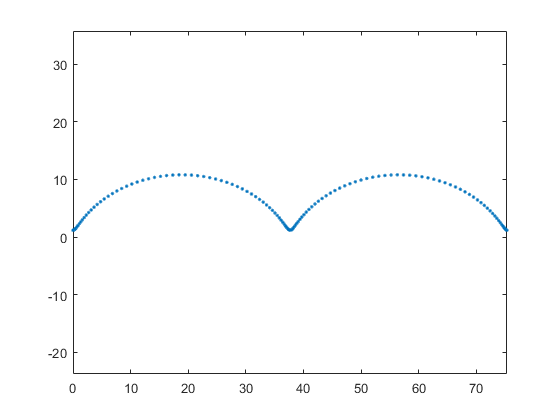

phi = [0:0.1:4*pi];
x_cg = r * phi - (r - ybar)*sin(phi);
y_cg = r - (r - ybar)*cos(phi);
plot(x_cg, y_cg, '.')
axis equal

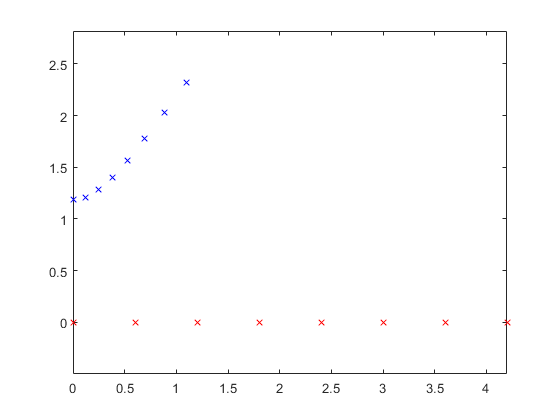

phi = [0:0.1:pi/4];
x_cg = r * phi - (r - ybar)*sin(phi);
y_cg = r - (r - ybar)*cos(phi);
x_cp = r * phi;
y_cp = zeros(size(phi));
plot(x_cg, y_cg, 'bx', x_cp, y_cp, 'rx')
axis equal

%define circular segment parameters
r=6;
h=2;

%ramp angle in degrees converted to radians
theta=deg2rad(35);

%specify symbolic values
syms r_sym h_sym y

%we need to setup our integrals. For the centroid, ybar=intydA/intdA 
%We use dA=xdy
  
%first define x using the definition of a circle with center at [0,R], x^2+(y-R)^2=R^2
x=sqrt(r_sym^2-(y-r_sym)^2);

%Setup the integral, symbolicaly for the area of the circular segment. This integral is A=2*int(x)dy
A=2*int(x,y,[0 h_sym]);

%do the integral for the centroid symbolically and convert to a double
ybar=int(y*x,y,[0 h_sym])/int(x,y,[0 h_sym]);

%substitute numerical values for r and h and convert the output to a double
A=double(subs(A,[r_sym, h_sym],[r, h]))

A = 12.3899

ybar=double(subs(ybar,[r_sym, h_sym],[r, h]))

ybar = 1.1873


% create the symbolic variable phi
syms phi

%position of the CG in global frame
i_cg=(r*phi-(r-ybar)*sin(phi))*cos(theta)+(r-(r-ybar)*cos(phi))*sin(theta);
j_cg=-(r*phi-(r-ybar)*sin(phi))*sin(theta)+(r-(r-ybar)*cos(phi))*cos(theta);

%position of contact point in global frame
i_contact=r*phi*cos(theta);
j_contact=r*phi*-sin(theta);

% find the equilibrium angle using the solve function
eqn = i_cg == i_contact; %create equality
phi_eq=rad2deg(double(solve(eqn,phi,'Real',true))) %use rad2deg to convert to degrees

phi_eq =    10.6502
   99.3498
